## Set up

clc
clear
clf
rng(16);

### Read

FullSet = readtable("results\Data\training_measured_data_combined.csv");

## Plotting setup

### Plot colours

% Plot colours
orange = '#FF9A5B';
blue   = '#06ACE9';
 SAVE_IMAGES= true;

### Plot style

% Plot style
line_width = 0.7;
font_size = 4;
current_fault = ':';
state_labels = ["PS-0: N.O." "PS-3: E.D." "PS-4: S.V." "PS-14: S.D." "PS-18: P.D." "PS-19 - E.D.+S.D." "PS-20 - E.D.+S.D.+P.D." "PS-21 - S.D.+P.D."]; %["PS-0: Normal Operation" "PS-3: Extractant Degradation" "PS-4: Stuck LO Valve" "PS-14: c_{RE} Sensor Drift" "PS-17: f_{PLSP} Sensor Gain" "PS-18: c_{LE} Precision Degradation"];

single_length = 259201;
step_time = 1;
FullSet.Cont_time = linspace(0, (7776000*5+30*4), length(FullSet.Time))';
FullSet.process_state(1:single_length) = 0;
FullSet.process_state((single_length+1):(single_length*2)) = 3;
FullSet.process_state((single_length*2+1):(single_length*3)) = 4;
FullSet.process_state((single_length*3+1):(single_length*4)) = 14;
FullSet.process_state((single_length*4+1):(single_length*5)) = 18;
FullSet.process_state((single_length*5+1):(single_length*6)) = 19;
FullSet.process_state((single_length*6+1):(single_length*7)) = 20;
FullSet.process_state((single_length*7+1):end) = 21;

model_time = FullSet.Cont_time/(60*60);
simulation_results.c_PLS_measured = FullSet.c_PLS_measured;
simulation_results.c_LE_measured = FullSet.c_LE_measured;
simulation_results.c_LE_sensor = FullSet.c_LE_sensor;
simulation_results.f_PLSP_measured = FullSet.f_PLSP_measured;
simulation_results.f_PLSP_sensor = FullSet.f_PLSP_sensor;
simulation_results.f_PLSS_measured = FullSet.f_PLSS_measured;
simulation_results.cLO_SP = ones(length(model_time), 1)*14.87991304;
simulation_results.c_LO_measured = FullSet.c_LO_measured;
simulation_results.c_LO_sensor = FullSet.c_LO_sensor;
simulation_results.cRE_SP = ones(length(model_time), 1)*54.95809839;
simulation_results.c_RE_measured = FullSet.c_RE_measured;
simulation_results.c_RE_sensor = FullSet.c_RE_sensor;
simulation_results.vLO_control_saturated = FullSet.v_LO_control;
simulation_results.vLO_valve = FullSet.v_LO_valve;
simulation_results.vLE_control_saturated = FullSet.v_LE_control;
simulation_results.vLE_valve = FullSet.v_LE_valve;
fault_state.Data = FullSet.fault_state;
process_state = FullSet.process_state;
% simulation_results.c_LE_sensor = FullSet.c_LE_

## Plot the measured process variables

### Plot the external variables

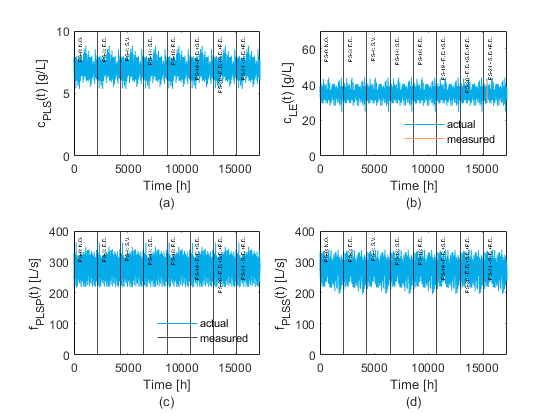

fault_check = false;
fault_red = 0;
fault_green = model_time(end);
fault_count = 1;
state_count = 2;
for i = (100/step_time+1):length(fault_state.Data)
    if fault_state.Data(i) == 0
        if fault_state.Data(i-1) == 0
        else
            fault_check = true;
            fault_green(fault_count) = i*step_time*30/3600;
            fault_count = fault_count+1;
        end
    else 
        if fault_state.Data(i-1) == 0
            fault_check = true;
            fault_red(fault_count) = i*step_time*30/3600;
        end
    end
    
end
new_state(1) = 0;
for i = 2:length(model_time)
    if process_state(i) ~= process_state(i-1)
        new_state(state_count) = i*30/3600;
        state_count = state_count+1;
    end
end

i_s = (single_length)*(current_fault)+1;
i_f = (current_fault+1)*single_length*1;
% t_s = (i_s*30-30)/3600;
% t_f = (i_f*30-30)/3600;
t_s = 1;
t_f = 'end';

% fault_red_update = zeros(1,2);
% fault_green_update = zeros(1,2);
% fault_red_update(1) = fault_red(6);
% fault_red_update(2) = 1852832*step_time*30/3600;
% fault_green_update(1) = 1854977*step_time*30/3600;
% fault_green_update(2) = 2073608*step_time*30/3600;

% Create the group of the external variables
figure()

% Plot c_PLS_measured
subplot(2,2,1)
plot(model_time(i_s:i_f), simulation_results.c_PLS_measured(i_s:i_f), '-', 'LineWidth', line_width ,'Color', blue)
hold on
% xline(new_state, 'k-', state_labels ,'LineWidth', line_width, 'FontSize', font_size)
hold off
ylabel("c_{PLS}(t) [g/L]")
xlabel(["Time [h]", "(a)"])
ylim([0 10])
xlim([t_s t_f])
% xlim([0 model_time(end)])

% Plot c_LE_measured
% subplot(2,2,2)
plot(model_time(i_s:i_f), simulation_results.c_LE_measured(i_s:i_f), '-', 'LineWidth', line_width ,'Color', blue)
hold on
plot(model_time(fault_state.Data == 21), simulation_results.c_LE_sensor(fault_state.Data == 21), '-', 'LineWidth', line_width ,'Color', orange)
% xline(new_state, 'k-', state_labels ,'LineWidth', line_width, 'FontSize', font_size)
if fault_check == true
%     xline(fault_red_update, 'r-', 'LineWidth', line_width)
%     xline(fault_green_update, 'g-', 'LineWidth', line_width)
    xline(fault_red(current_fault), 'r-', 'LineWidth', line_width)
    xline(fault_green(current_fault), 'g-', 'LineWidth', line_width)
end
hold off
    legend({'actual', 'measured','','',''}, 'Location', 'southeast')

legend('boxoff')
hold off
ylabel("c_{LE}(t) [g/L]")
xlabel(["Time [h]", "(b)"])
ylim([0 70])
xlim([t_s t_f])
% xlim([0 model_time(end)])

% Plot f_PLSP_measured
subplot(2,2,3)

plot(model_time(i_s:i_f), simulation_results.f_PLSP_measured(i_s:i_f), '-', 'LineWidth', line_width ,'Color', blue)
hold on


plot(model_time(fault_state.Data == 17), simulation_results.f_PLSP_sensor(fault_state.Data == 17), '-', 'LineWidth', line_width/2, 'Color', orange)
% xline(new_state, 'k-', state_labels ,'LineWidth', line_width, 'FontSize', font_size)
if fault_check == true
    xline(fault_red(current_fault), 'r-', 'LineWidth', line_width)
    xline(fault_green(current_fault), 'g-', 'LineWidth', line_width)
end
hold off

    legend({'actual','measured','',''}, 'Location', 'southeast')

legend('boxoff')

ylabel("f_{PLSP}(t) [L/s]")
xlabel(["Time [h]", "(c)"])
ylim([0 400])
xlim([t_s t_f])
% xlim([0 model_time(end)])

% Plot f_PLSS_measured
subplot(2,2,4)
plot(model_time(i_s:i_f), simulation_results.f_PLSS_measured(i_s:i_f), '-', 'LineWidth', line_width ,'Color', blue)
hold on
xline(new_state, 'k-', state_labels ,'LineWidth', line_width, 'FontSize', font_size)
hold off
ylabel("f_{PLSS}(t) [L/s]")
xlabel(["Time [h]", "(d)"])
ylim([0 400])
xlim([t_s t_f])

% xlim([0 model_time(end)])


% Save the current figure
if (SAVE_IMAGES)
%     print('results/Data/graphs/testing/external_variables_fault_21_zoom', '-dpng', '-r600')
end

### Plot the controlled variables

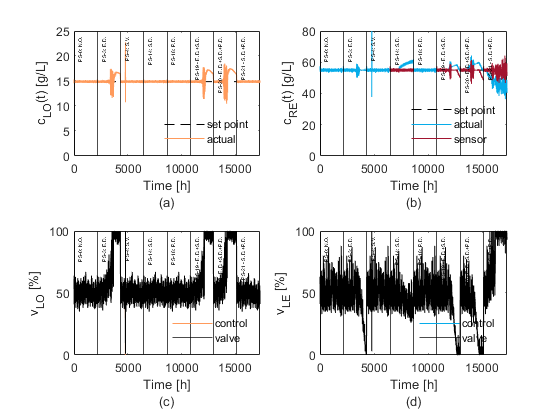

% Create the group of the controlled variables
figure()

i_s = (single_length)*(current_fault)+1;
i_f = (current_fault+1)*single_length*1;
% t_s = (i_s*30-30)/3600;
% t_f = (i_f*30-30)/3600;
t_s = 1;
t_f = 'end';

fault_red_update = zeros(1,2);
fault_green_update = zeros(1,2);
fault_red_update(1) = fault_red(6);
fault_red_update(2) = 1852832*step_time*30/3600;
fault_green_update(1) = 1854977*step_time*30/3600;
fault_green_update(2) = 2073608*step_time*30/3600;

% Plot c_LO_measured
subplot(2,2,1)
plot(model_time(i_s:i_f), simulation_results.cLO_SP(i_s:i_f), 'k--', 'LineWidth', line_width)
hold on

plot(model_time(i_s:i_f), simulation_results.c_LO_measured(i_s:i_f), '-', 'LineWidth', line_width ,'Color', orange)
% xline(new_state, 'k-', state_labels ,'LineWidth', line_width, 'FontSize', font_size)
if fault_check == true
%     xline(fault_red_update, 'r-', 'LineWidth', line_width)
%     xline(fault_green_update, 'g-', 'LineWidth', line_width)
    xline(fault_red(current_fault), 'r-', 'LineWidth', line_width)
    xline(fault_green(current_fault), 'g-', 'LineWidth', line_width)
end

legend({'set point','actual','',''}, 'Location', 'southeast')
legend('boxoff')
hold off

ylabel("c_{LO}(t) [g/L]")
xlabel(["Time [h]", "(a)"])
ylim([0 25])
xlim([t_s t_f])
% xlim([0 model_time(end)])

% Plot c_RE_measured
subplot(2,2,2)
plot(model_time(i_s:i_f), simulation_results.cRE_SP(i_s:i_f), 'k--', 'LineWidth', line_width)
hold on

plot(model_time(i_s:i_f), simulation_results.c_RE_measured(i_s:i_f), '-', 'LineWidth', line_width ,'Color', blue)

plot(model_time(process_state == 14), simulation_results.c_RE_sensor(process_state == 14), '-', 'LineWidth', line_width/2, 'Color', '#A2142F')
plot(model_time(process_state == 19), simulation_results.c_RE_sensor(process_state == 19), '-', 'LineWidth', line_width/2, 'Color', '#A2142F')
plot(model_time(process_state == 20), simulation_results.c_RE_sensor(process_state == 20), '-', 'LineWidth', line_width/2, 'Color', '#A2142F')
plot(model_time(process_state == 21), simulation_results.c_RE_sensor(process_state == 21), '-', 'LineWidth', line_width/2, 'Color', '#A2142F')
% xline(new_state, 'k-', state_labels ,'LineWidth', line_width, 'FontSize', font_size)
if fault_check == true
%     xline(fault_red_update, 'r-', 'LineWidth', line_width)
%     xline(fault_green_update, 'g-', 'LineWidth', line_width)
    xline(fault_red(current_fault), 'r-', 'LineWidth', line_width)
    xline(fault_green(current_fault), 'g-', 'LineWidth', line_width)
end

legend({'set point','actual', 'sensor','',''}, 'Location', 'southeast')
legend('boxoff')

hold off

ylabel("c_{RE}(t) [g/L]")
xlabel(["Time [h]", "(b)"])
ylim([0 80])
xlim([t_s t_f])
% xlim([0 model_time(end)])

% Plot v_LO
subplot(2,2,3)
plot(model_time(i_s:i_f), simulation_results.vLO_control_saturated(i_s:i_f)*100, '-', 'LineWidth', line_width, 'Color', orange)
hold on
% xline(new_state, 'k-', state_labels ,'LineWidth', line_width, 'FontSize', font_size)
plot(model_time(i_s:i_f), simulation_results.vLO_valve(i_s:i_f)*100, 'k-', 'LineWidth', line_width)
if fault_check == true
%     xline(fault_red_update, 'r-', 'LineWidth', line_width)
%     xline(fault_green_update, 'g-', 'LineWidth', line_width)
    xline(fault_red(current_fault), 'r-', 'LineWidth', line_width)
    xline(fault_green(current_fault), 'g-', 'LineWidth', line_width)
end
hold off
legend({'control','valve'}, 'Location', 'southeast')
legend('boxoff')
ylabel("v_{LO} [%]")
xlabel(["Time [h]", "(c)"])
ylim([0 100])
xlim([t_s t_f])
% xlim([0 model_time(end)])

% Plot v_LE
subplot(2,2,4)
plot(model_time(i_s:i_f), simulation_results.vLE_control_saturated(i_s:i_f)*100, '-', 'LineWidth', line_width,'Color', blue)
hold on
% xline(new_state, 'k-', state_labels ,'LineWidth', line_width, 'FontSize', font_size)
plot(model_time(i_s:i_f), simulation_results.vLE_valve(i_s:i_f)*100, 'k-', 'LineWidth', line_width)
if fault_check == true
%     xline(fault_red_update, 'r-', 'LineWidth', line_width)
%     xline(fault_green_update, 'g-', 'LineWidth', line_width)
    xline(fault_red(current_fault), 'r-', 'LineWidth', line_width)
    xline(fault_green(current_fault), 'g-', 'LineWidth', line_width)
end
hold off
legend({'control', 'valve'}, 'Location', 'southeast')
legend('boxoff')
ylabel("v_{LE} [%]")
xlabel(["Time [h]", "(d)"])
ylim([0 100])
xlim([t_s t_f])

% %xlim([0 model_time(end)])


% Save the current figure
if (SAVE_IMAGES)
%     print('results/Data/graphs/testing/controlled_variables_fault_211', '-dpng', '-r600')
end